# MATLAB基本绘图操作

## 二维图片操作

x = 0:0.01:pi; % 从 0 到 pi ，步长为0.01
y = sin(x)

y =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0699    0.0799    0.0899    0.0998    0.1098    0.1197    0.1296    0.1395    0.1494    0.1593    0.1692    0.1790    0.1889    0.1987    0.2085    0.2182    0.2280    0.2377    0.2474    0.2571    0.2667    0.2764    0.2860    0.2955    0.3051    0.3146    0.3240    0.3335    0.3429    0.3523    0.3616    0.3709    0.3802    0.3894    0.3986    0.4078    0.4169    0.4259    0.4350    0.4439    0.4529    0.4618    0.4706


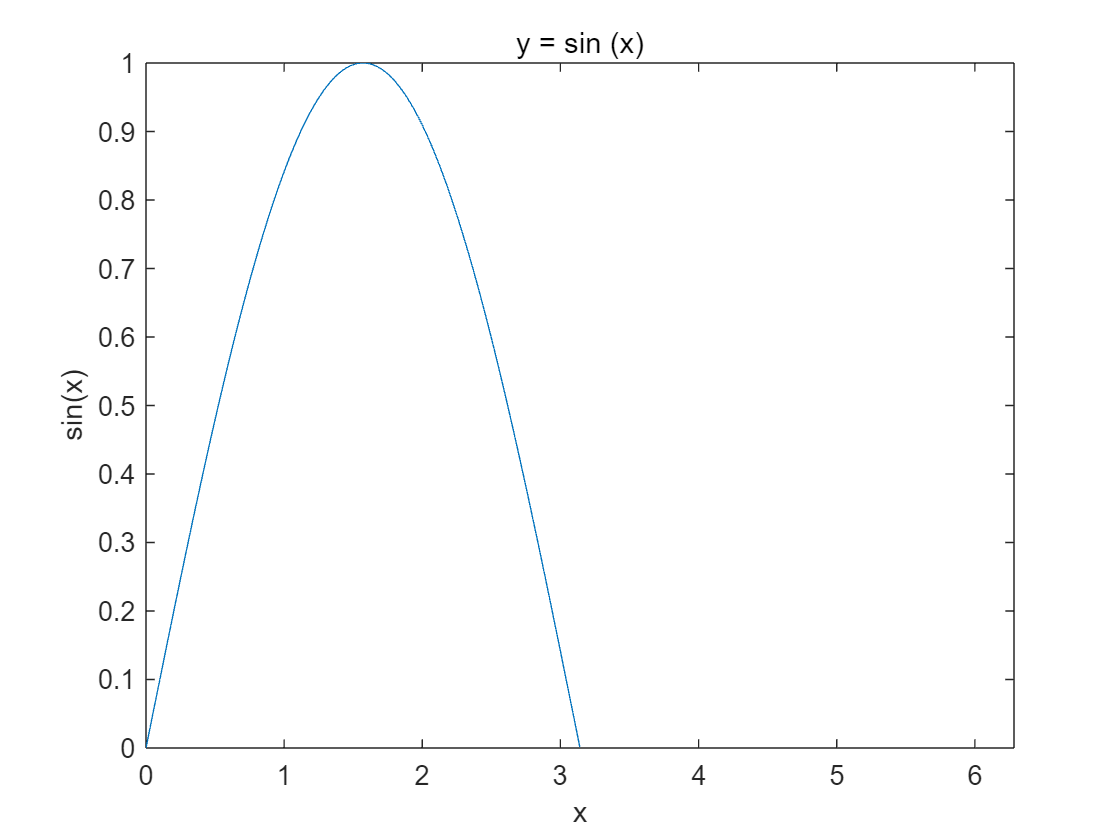

figure % 创建一个幕布
plot(x,y); % 二维线图
title('y = sin (x)'); % 添加标题
xlabel('x'); % x 轴添加标签
ylabel('sin(x)'); % y 轴添加标签
xlim([0 2*pi]) % 设置x轴的坐标范围

% 特殊符号设置
x = 0:0.01:20;
y1 = 200 * exp(-0.05 * x) .* sin(x);    % exp()指数函数 (.)各项运算
y2 = 0.8 * exp(-0.5 * x) .* sin(10 * x)

y2 =          0    0.0795    0.1574    0.2329    0.3054    0.3741    0.4384    0.4976    0.5514    0.5991    0.6403    0.6748    0.7022    0.7223    0.7351    0.7403    0.7382    0.7287    0.7120    0.6884    0.6582    0.6217    0.5794    0.5318    0.4793    0.4225    0.3621    0.2987    0.2330    0.1656    0.0972    0.0285   -0.0398   -0.1070   -0.1725   -0.2356   -0.2957   -0.3523   -0.4048   -0.4527   -0.4957   -0.5333   -0.5652   -0.5911   -0.6109   -0.6245   -0.6316   -0.6324   -0.6269   -0.6152


help plot

 plot - 二维线图
    此 MATLAB 函数 创建 Y 中数据对 X 中对应值的二维线图。 要绘制由线段连接的一组坐标，请
    将 X 和 Y 指定为相同长度的向量。 要在同一组坐标区上绘制多组坐标，请将 X 或 Y 中的至少
    一个指定为矩阵。

    向量和矩阵数据
        plot(X,Y)
        plot(X,Y,LineSpec)
        plot(X1,Y1,...,Xn,Yn)
        plot(X1,Y1,LineSpec1,...,Xn,Yn,LineSpecn)
        plot(Y)
        plot(Y,LineSpec)

    表数据
        plot(tbl,xvar,yvar)
        plot(tbl,yvar)

    其他选项
        plot(ax,___)
        plot(___,Name,Value)
        p = plot(___)

    输入参数
        X - x 坐标
            标量 | 向量 | 矩阵
        Y - y 坐标
            标量 | 向量 |

help yyaxis

 yyaxis - 创建具有两个 y 轴的图
    此 MATLAB 函数 激活当前坐标区中与左侧 y 轴关联的一侧。后续图形命令的目标为左侧。如果当
    前坐标区中没有两个 y 轴，此命令将添加第二个 y 轴。如果没有坐标区，此命令将首先创建坐标
    区。

    yyaxis left
    yyaxis right

    yyaxis(ax,___)

    输入参数
        ax - 目标坐标区
            当前坐标区 (默认值) | Axes 对象

    打开示例
        绘制带有两个 y 轴的数据图
        为每一侧添加标题和轴标签
        在每一侧绘制多组数据
        控制每侧的颜色
        控制单个绘图的颜色
        为特定坐

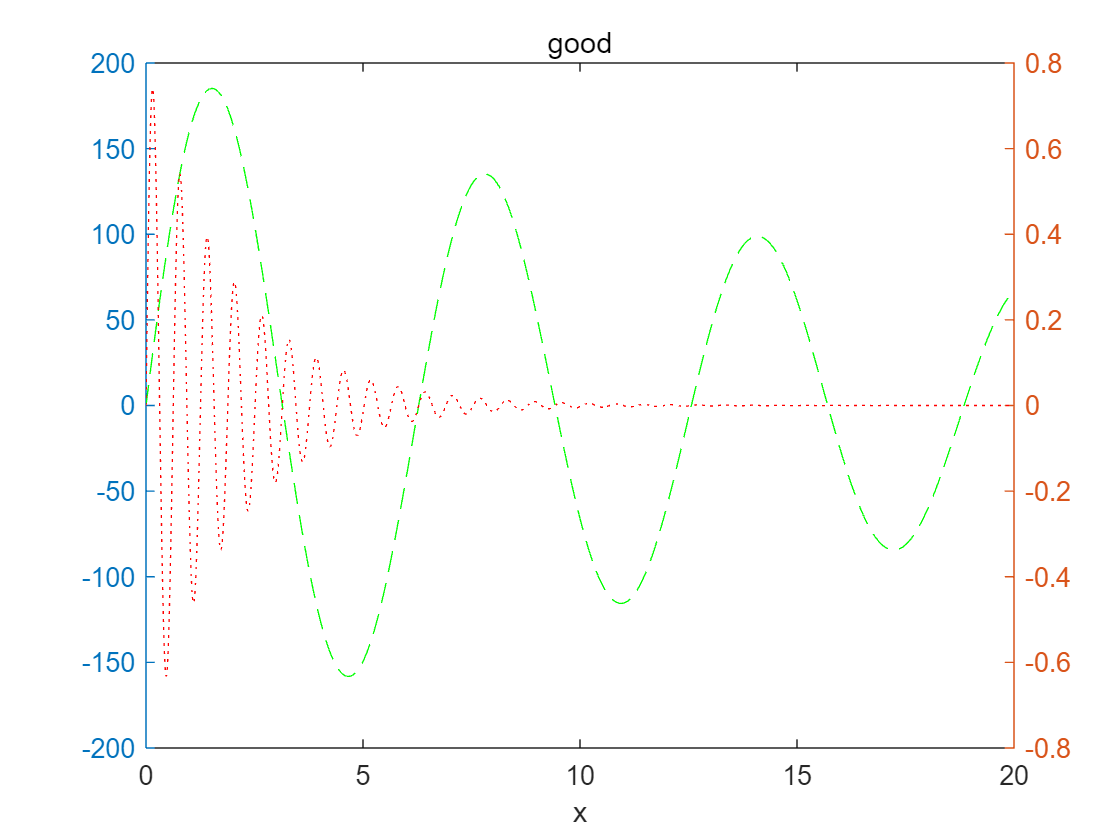

figure  % 公用一个x坐标系，对应两个y轴
title("good")
xlabel('x')
yyaxis left
plot(x,y1,'g--');

yyaxis right
plot(x,y2,'r:')

## 三维立体绘图

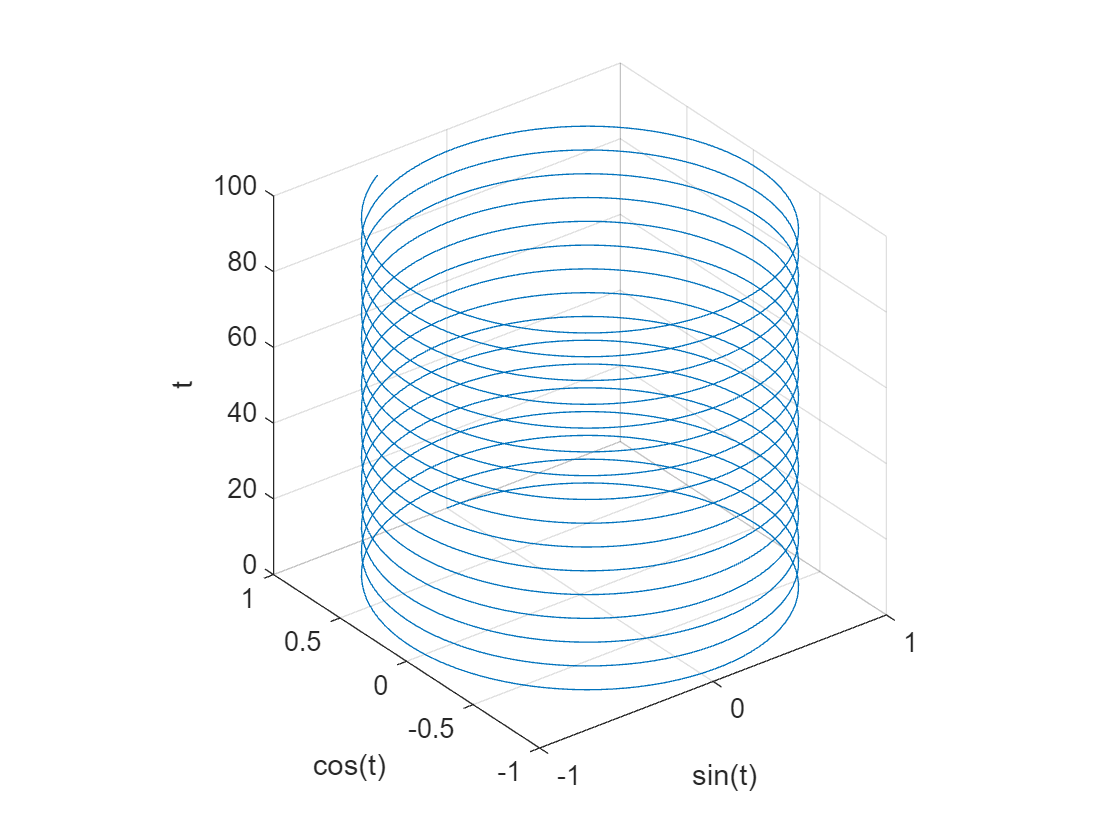

t = 0:pi/50:100*pi;
figure
plot3(sin(t),cos(t),t)
xlabel('sin(t)')
ylabel('cos(t)')
zlabel('t')
zlim([0,100])

hold on     % 保存当前图片
grid on     % 加上坐标系网格线
axis square % 坐标系正方形

## 图片保存与导出

figure -> 图片复制\图片另存为

figure -> 文件 -> 导出设置（调整图片大小）

## 双峰图形

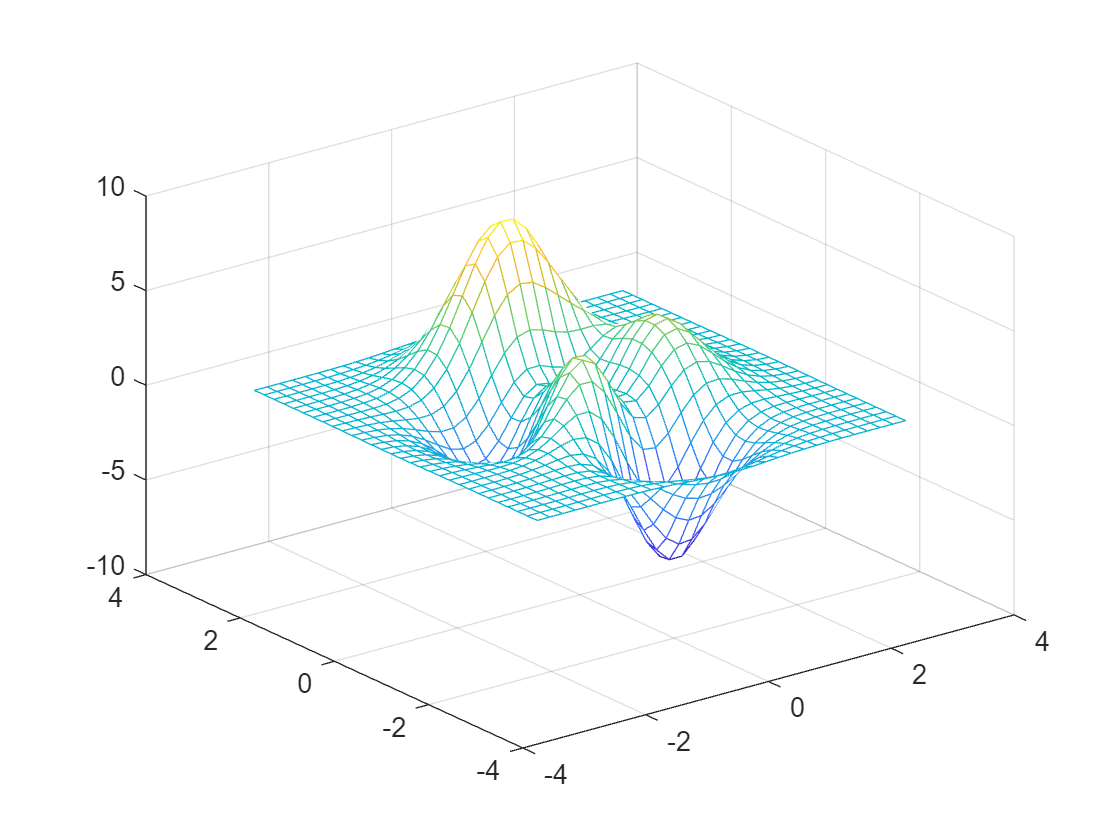

figure
[x,y,z] = peaks(30);
mesh(x,y,z)         % 网格曲面图
grid on             % 坐标系网格线